#  Reglas de derivadas para funciones trascendentales 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Para algunas funciones comunes, aplicar la definición límite de la derivada requiere pruebas límite más complicadas que las requeridas para polinomios. Este script presenta las derivadas de senos, cosenos, exponenciales y logaritmos naturales a través de aproximación numérica. 

**Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Si encuentra que la codificación MATLAB en este script es desafiante, considere tomar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) , un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y los pasos en la secuencia dada. Pase a una nueva sección solo después de completar la anterior. 

##  ¿Qué es una función trascendental? 

 ¿Ha encontrado números trascendentales como $e\approx 2.71828182459046$ o $\pi \approx 3.141592653589793$ ? Se llaman * trascendentales * porque no son * algebraicos, * es decir, no son una raíz de ninguna ecuación polinomial de grado finito con coeficientes enteros. Todos los números racionales son algebraicos, por ejemplo, $x = \frac{p}{q}$ es una raíz de $y = qx-p$ , pero muchos números irracionales también son algebraicos, por ejemplo, $x=\sqrt{5}$ es una raíz de $y=x^2-5$. A pesar de la falta de una ecuación polinómica de grado finito relacionada, aún puedes aproximar números trascendentales por su secuencia de expansiones decimales, p. ej., 3, 3.1, 3.14, 3.141, 3.1415, 3.14159, etc. Una función trascendental   es una función que puedes aproximar por una secuencia de funciones polinómicas, pero que no es la solución a una ecuación polinómica en sí. Las funciones trascendentales más comunes son las funciones exponenciales, logarítmicas y trigonométricas. 

##  Aproximación numérica 

 Recuerda el enfoque gráfico para entender la definición límite de la derivada como [Aproximación por líneas secantes](matlab:open('./Definition.mlx')) aproximarse a una línea tangente. Este script se basará en esa misma idea al identificar puntos adyacentes separados por un pequeño tamaño de paso en una curva y evaluar la pendiente de la línea secante a través de esos puntos. A medida que el tamaño del paso se hace más pequeño, la pendiente de la línea secante se aproximará numéricamente a la pendiente de la línea tangente. Hay cursos completos y programas de investigación dedicados al análisis numérico que plantean y responden preguntas sobre la mejor manera de describir y calcular estas aproximaciones, pero eso está más allá del alcance de este guión. 

##  Funciones trigonométricas 

 Las funciones trigonométricas son la familia de funciones que relacionan las razones de los lados con los ángulos en triángulos rectángulos. 

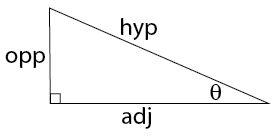

 Las abreviaturas son 

 opp = "longitud del lado opuesto al ángulo $\theta$ ", 

 adj = "longitud del lado entre el ángulo recto y el ángulo $\theta$ ", 

 y 

 hyp = "longitud de la hipotenusa". 

###  Senos & Cosenos 

 La función $y = \sin(\theta)$ rastrea la razón $\frac{\text{opp}}{\text{hyp}}$. 

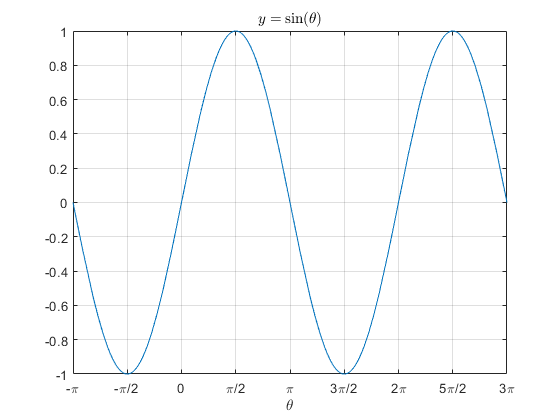

 La función $y=\cos(\theta)$ rastrea la razón $\frac{\text{adj}}{\text{hyp}}$. 

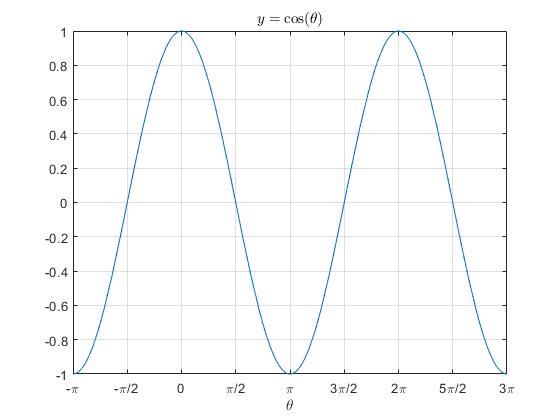

 Al colocar un triángulo rectángulo en un círculo unitario, la relación íntima entre senos y cosenos se vuelve clara. 

 Esto se muestra en el archivo [UnitCircleAnimation.mp4](matlab: OpenOnComputer("UnitCircleAnimation.mp4")) o generando la animación a continuación: 

  
UnitCircleAnimation();

  ** Consejo profesional **. Si este script se ejecuta demasiado lento, puede hacer clic en el botón ** Detener ** en la pestaña ** Editor en vivo **. Eso terminará el script. 

###  Derivada de seno 

** Actividad. ** Intentemos determinar la derivada $\frac{dy}{d\theta}$ de $y=\sin(\theta)$ calculando su aproximación numérica. Primero, escojamos un tamaño de paso $h$ para usar en el cociente de diferencias: 

$\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$ , 

 y grafiquemos el resultado: 

h = 0.2;                %Tamaño de paso definido por el usuario establecido para no permitir h = 0, predeterminado 0.2
                       %Ejecutar esta sección
if ~exist("sinTHandle","var") || ~isvalid(sinTHandle)
    figure                                      %Inicializar una figura
    [sinsHandle,sinmptHandle,sinTHandle] = GraphApproxDer(@(t)sin(t),"sin",h,[-pi 3*pi]);
    %GraphApproachDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    UpdateDerApprox(@(t)sin(t),"sin",h,[-pi 3*pi],sinsHandle,sinmptHandle,sinTHandle)
end

  ** Prueba **. Haz que el valor del tamaño del paso sea más grande y más pequeño y observa el impacto en la derivada aproximada de $\sin(\theta)$ que se muestra en el gráfico anterior. 

** Ejercicio 1 **. Considera la derivada aproximada $\frac{d}{d\theta}\left[\sin(\theta)\right]$ que se grafica arriba. 

-  ¿Podría ser la derivada una función polinómica? ¿Por qué o por qué no? 

poly = "idk";         %Respuesta definida por el usuario a la Pregunta 1.1
%Si la respuesta ha cambiado del valor predeterminado, "No sé", muestra la retroalimentación
% adecuada.
if poly == "yes"
    disp("Todos los polinomios p(t) divergen hacia el infinito positivo o negativo a medida que p tiende a infinito.")
    disp("Eso no es cierto para esta derivada. No es un polinomio.")
elseif poly == "no"
    disp("Eso es correcto.")
    disp("Esto no puede ser un polinomio porque no tiene el comportamiento límite correcto.")
end

 2. ¿La derivada tiene asíntotas? ¿Por qué o por qué no? Si hay asíntotas, ¿cuáles son? 

asymptotes = "idk";   %Respuesta definida por el usuario sobre si hay asíntotas y de qué tipo
yasymp = 0.5;       %Si hay una asíntota horizontal, el usuario debe establecer el valor aquí
xasymp = 0.5;       %Si hay una asíntota vertical, el usuario debe establecer el valor aquí
%En este caso no hay asíntotas, pero para lograr simetría con preguntas
% posteriores, aquí también se incluye la opción de definirlas
% Si la respuesta ha cambiado del valor predeterminado, "No sé", muestra
% la respuesta correspondiente.
if (asymptotes == "yHoriz") || (yasymp ~= 0.5)
    disp("No, no hay una asíntota horizontal. Por favor, intenta de nuevo.")
elseif (asymptotes == "yVert") || (xasymp ~= 0.5)
    disp("No, no hay una asíntota vertical. Por favor, intenta de nuevo.")
elseif asymptotes == "no"
    disp("Correcto. La derivada no tiene ninguna asíntota.")
end

 3. ¿La derivada es periódica? ¿Por qué o por qué no? Si es periódica, ¿cuál es el período y cuál es la amplitud pico? 

periodic = -1;   %Respuesta definida por el usuario sobre si la derivada es periódica
%Interactúa con el usuario en función de sus elecciones, con mensajes específicos
% etiquetados en las opciones predeterminadas que se han elegido como incorrectas
if periodic == 1
    disp("Sí, esta derivada es periódica. Por favor, establece el período y la amplitud correctos:")
    period = pi;          amplitude = 0.5;
    if period == 2*pi
        disp("El período es correcto.")
    elseif abs(period-2*pi) < .0033    % Verificar si la respuesta se basa en 3.14 en lugar de pi
        disp("Por favor, usa el valor exacto pi en lugar de la aproximación 3.14.")
    elseif period == pi
        disp("El período no es pi.")
        disp("Las líneas azules discontinuas muestran el período propuesto.")
    else
        disp("El período es incorrecto. Por favor, intenta de nuevo.")
        disp("Las líneas azules discontinuas muestran el período propuesto.")
    end
    if amplitude == 1
        disp("La amplitud es 1, eso es correcto.")
    elseif abs(amplitude-1) < .01       % Solicitar al usuario que encuentre el valor exacto
        disp("Por favor, sé más preciso. La amplitud es un número entero.")
    elseif amplitude == 1/2
        disp("La amplitud no es 1/2.")
        disp("Las líneas rojas punteadas muestran la amplitud propuesta.")
    else
        disp("La amplitud es incorrecta. Por favor, intenta de nuevo.")
        disp("Las líneas rojas punteadas muestran la amplitud propuesta.")
    end
    if ~exist("h","var")
        h = .2                                     %Establecer el tamaño de paso predeterminado si no está definido por el usuario
    end
    GraphApproxDer(@(t)sin(t),"sin",h,[-pi 3*pi]); %GraphAppDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    if abs(amplitude)>1                   %Redimensionar el gráfico para mostrar la línea de amplitud propuesta
        ylim([-1.1 1.1*abs(amplitude)]);
    end
    hold on
    xline(0,"--",SeriesIndex=1)           %Grafica el período propuesto en x=0 y x=período, línea azul discontinua
    xline(period,"--",SeriesIndex=1)
    yline(0,":",SeriesIndex=2)            %Grafica la amplitud propuesta en y=0 e y=amplitud, línea roja punteada
    yline(amplitude,":",SeriesIndex=2)
    hold off
elseif periodic == 0                      %Si la solución es incorrecta, ofrecer una pista
    disp("No, eso es incorrecto. ¿Esta función se repite alguna vez?")
end

** Ejercicio 2 **. Teniendo en cuenta los resultados del Ejercicio 1, la derivada $y'(\theta)$ debería ser una función que reconozcas. Usa el nombre de la variable independiente `t for`$\theta$ , ¿cuál es la derivada de `sin(t)` con respecto a `t` ? 

derGuess = @(t)t;  %Función simbólica anónima definida por el usuario, predeterminada @(t)t
                            %Ejecutar esta sección
CheckSinDer(derGuess)                 %checkSinDer está definido en Funciones auxiliares Funciones
% checkSinDer takes the function handle derGuess and checks whether it is equivalent
% to the derivative of sin(t)

###  Derivada del coseno 

** Actividad **. Intenta determinar la derivada $\frac{dy}{d\theta}$ de $y=\cos(\theta)$ calculando su aproximación numérica tal como lo hiciste para $\sin(\theta)$ arriba. Primero, elige un tamaño de paso $h$ para usar en el cociente de diferencias, $\frac{dy}{d\theta} \approx \frac{y(\theta+h)-y(\theta)}{h}$ , y grafica el resultado nuevamente. 

h = 0.2;               %Tamaño de paso definido por el usuario, predeterminado h = 0,2
                           %Ejecutar esta sección
if ~exist("cosTHandle","var") || ~isvalid(cosTHandle)
    figure                                     %Inicializar una figura
    [cossHandle,cosmptHandle,cosTHandle] = GraphApproxDer(@(t)cos(t),"cos",h,[-pi 3*pi]);
    %GraphAppDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    UpdateDerApprox(@(t)cos(t),"cos",h,[-pi 3*pi],cossHandle,cosmptHandle,cosTHandle)
end

 Recuerda que la derivada de $y=\sin(\theta)$ era $y' = \sin\left(\theta+\frac{\pi}{2}\right)$. Parece que la derivada de $y=\cos(\theta)$ también es una función sinusoidal con la misma amplitud. Usa el control deslizante para probar los valores del cambio de fase $\phi$ para determinar la función $\frac{d}{d\theta}\left[\cos(\theta)\right] = \cos(\theta+\phi)$. Quieres que la línea azul sólida pase por los puntos cuadrados. 

mult = 0;            %Multiplicador definido por el usuario, valor predeterminado mult = 0
if ~exist("h","var")
    h = .2                                      %Si no está definido por el usuario, establecer h = 0,2 por defecto
end
figure                                          %Inicializar una figura
GraphApproxDer(@(t)cos(t),"cos",h,[-pi 3*pi]);  %GraphAppDer está definido en Funciones auxiliares
%GraphAppDer traza una función y calcula y traza su derivada numérica
% con un tamaño de paso h
hold on
GraphDerGuess(@(t)cos(t),mult)                  %graphDerGuess está definido en Funciones auxiliares
% graphDerGuess plots the function given by fh with a phase shift of mult*pi
%      and adds annotation noting that \phi = mult*pi on the plot
%      in the lower left hand quadrant of the plot
hold off

 Una vez que haya elegido la mejor función posible para ajustar la derivada aproximada, puede verificar su resultado aquí usando `t` como su variable independiente. Si lo desea, también puede usar `phi` para el valor $\phi$ que estableció anteriormente o `pi` para el valor $\pi$ : 

phi = mult*pi;                                 %Multiplicador definido por el usuario basado en el control deslizante mult anterior
cosDerGuess = @(t)t*phi*pi;        %Función anónima definida por el usuario, predeterminada @(t) t*phi*pi
                                     %Ejecutar esta sección
CheckCosDer(cosDerGuess)                       %checkCosDer está definido en Funciones auxiliares
% checkCosDer compares the derivative of cos(t) to fh(t) and prints a message
%      of success or failure using disp()

  ** Intenta **

 ¿Qué pasa si observas la derivada de $y=\sin(c\theta)$ para algún valor constante $c$ ? 

h = 0.021;             %Tamaño de paso definido por el usuario, predeterminado h = 0.021
c = 3;                       %Valor constante (numérico) definido por el usuario, predeterminado c=3
if abs(c)>1
    bds = [-pi 3*pi];
else
    bds = [-pi abs(3/c)*pi];
end
                            %Ejecutar esta sección
if ~exist("sincTHandle","var")||~isvalid(sincTHandle)
    figure                                      %Inicializar una figura
    [sincHandle,sincmptHandle,sincTHandle,sincFH] = GraphApproxDer(@(t)sin(c*t),"sin",h,bds);
    %GraphAppDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    sincTHandle.String = "$y = \sin(c\theta)$ con $c = $" + c;
    legend("$\sin(c\theta)$","Puntos Seleccionados","Cociente Diferencial","AutoUpdate","off")
    ax = sincTHandle.Parent;
    if abs(1.1*c)>1.1
        ax.YLim = [-abs(1.1*c) abs(1.1*c)];
    else
        ax.YLim = [-1.1 1.1];
    end
else
    UpdateDerApprox(@(t)sin(c*t),"sin",h,bds,sincHandle,sincmptHandle,sincTHandle)
    if c == round(c,0)
        sincStr = compose("$y = \\sin(%.0f\\theta)$",c);
    elseif c == round(c,1)
        sincStr = compose("$y = \\sin(%.1f\\theta)$",c);
    elseif c == round(c,2)
        sincStr = compose("$y = \\sin(%.2f\\theta)$",c);
    else
        sincStr = "$y = \sin(c\theta)$ with $c = $" + c;
    end
    sincTHandle.String = sincStr;
    sincFH.Function = sin(c*t);
    if abs(1.1*c)>1.1
        ax.YLim = [-abs(1.1*c) abs(1.1*c)];
        ax.XLim = [-pi 3*pi];
    else
        ax.YLim = [-1.1 1.1];
        ax.XLim = [-pi abs(3/c)*pi];
    end
end

 ** Reflexiona **

-  ¿Cuál es la derivada $y'(\theta)$ de la función $y = \sin(7\theta)$? ¿Cuál es la derivada $y'(\theta)$ de la función $y=\sin(-.36\theta)$? 

-  ¿Cuál crees que es la derivada $\frac{dy}{d\theta}$ de la función $y = \cos(c\theta)$ para algún valor constante $c$? ¿Por qué? 

-  ¿Cuál crees que es la derivada $\frac{d}{d\theta}\left[\sin(\theta + \phi)\right]$ para algún valor constante $\phi$? ¿Por qué? 

##  Segundas derivadas 

 Como se discutió en [Definition.mlx](matlab:open('./Definition.mlx')), la derivada es un operador lineal. En particular, dado que la derivada de una función es otra función, es posible tomar varias derivadas en secuencia: 

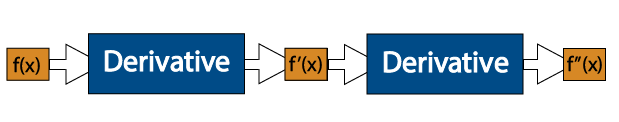

 Supongamos que las unidades de $f(x)$ son ranas y las unidades de $x$ son pies. Entonces 

$f(x)$ es el número de ranas 

$f'(x)$ es el número de ranas por pie ( $\frac{\text{frogs}}{\text{foot}}$ ) 

$f^{\prime \prime}(x)$ es el número de ranas por pie cuadrado ( $\frac{\text{frogs/foot}}{\text{foot}} = \frac{\text{frogs}}{\text{foot}^2}$ ) 

 ** Notación para derivadas de orden superior **

 Notación prima 

$f(x)$ , $f'(x)$ , $f''(x)$ , $f'''(x)$ , $f^{(iv)}(x)$ , $f^{(v)}(x)$ , $\ldots$ , $f^{(n)}(x)$

 Notación diferencial 

$f(x)$ , $\frac{df}{dx}$ , $\frac{d^2f}{dx^2}$ , $\frac{d^3f}{dx^3}$ , $\frac{d^4f}{dx^4}$ , $\frac{d^5f}{dx^5}$ , $\ldots$ , $\frac{d^nf}{dx^n}$

 Notación del operador 

$f(x)$ , $\frac{d}{dx}[f]$ , $\frac{d}{dx}\left[\frac{d}{dx}[f]\right] = \frac{d^2}{dx^2}[f]$ , $\frac{d}{dx}\left[\frac{d}{dx}\left[\frac{d}{dx}[f]\right]\right] = \frac{d^3}{dx^3}[f]$ , $\ldots$ , $\frac{d^n}{dx^n}[f]$

** Ejercicio 3 **. 

 La notación para la derivada $n^{\text{th}}$ de $g$ con respecto a $y$ es $\frac{d^ng}{dy^n}$ o $g^{(n)}(y)$ o $\frac{d^n}{dy^n}\left[g\right]$. 

 Si las unidades de $g$ son 

gUnits = "";            %Etiquetado de cadenas definido por el usuario de las unidades de la variable dependiente

 y las unidades de $y$ son 

yUnits = "";            %Etiquetado de cadenas definido por el usuario de las unidades de la variable independiente
                            %Ejecutar sección
if gUnits ~= "" && yUnits ~= ""           % Check for non-empty unit labels
    [n,opts] = SetOptions(gUnits,yUnits); %setOptions está definido en Funciones auxiliares
    % setOptions sets up the unit options and selects the power n
    % for reference use in the drop-down menu dngdyn below
elseif (gUnits ~= "") && (yUnits == "")   % Prompt the user to enter a string in yUnits
    disp("Necesitas establecer valores para las unidades de y para completar el Ejercicio 3.")
elseif (gUnits == "") && (yUnits ~= "")   % Solicitar al usuario que ingrese una cadena en gUnits
    disp("Necesitas establecer valores para las unidades de g para completar el Ejercicio 3.")
else                                      % Solicitar al usuario que ingrese cadenas tanto en gUnits como en yUnits
    disp("Necesitas establecer valores para las unidades de g y las unidades de y para completar el Ejercicio 3.")
end

dngdyn = 0;  % User-defined answer to Exercise 3, default "Unknown" with value 0
if dngdyn == 0                  % If the user has not changed the default value
    disp("Es posible determinar las unidades de la derivada.")
end
% Utilizar una estructura try/catch para reemplazar el error de "Variables desconocidas" con retroalimentación constructiva
try                          % Si el código dentro del try genera un error, el bloque catch
    CheckGYUnits(dngdyn,n);  % se ejecuta en lugar de terminar el script con un error que
catch                        % saca al usuario del modo "Ocultar Código"
    warning("Necesitas generar el problema en el Ejercicio 3 antes de poder resolverlo.")
end

###   Aplicación: Resortes 

 Consideremos un sistema simple masa-resorte con masa $m$ y coeficiente de rigidez $k>0$ : 

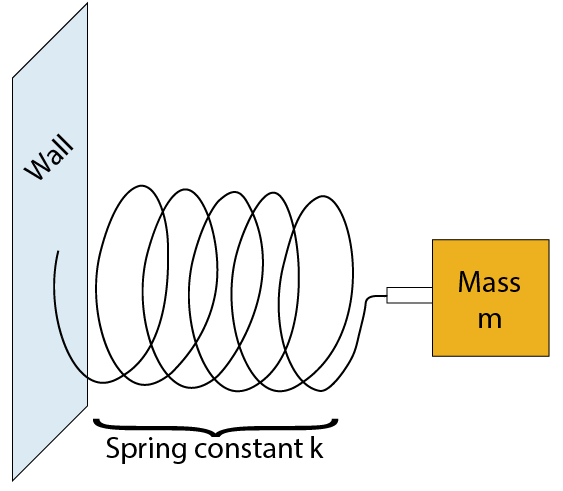

 Entonces el movimiento de la masa como función del desplazamiento horizontal $x = p(t)$ está dado por una ecuación diferencial (es decir, una ecuación que involucra derivadas): 

                                         
$$\text{Force} = -k\cdot \left(\text{Displacement from Equilibrium}\right)$$



$$\text{Mass} \times \text{Acceleration} = -k\cdot p(t)$$
                            


$$m\cdot \frac{d}{dt}\left[\frac{d}{dt}\left[p(t)\right]\right] = -k\cdot p(t)$$
                      

$\frac{d^2p}{dt^2} = -\frac{k}{m}p(t)$ , 

 donde la fuerza generada por el resorte está actuando en oposición al desplazamiento desde el equilibrio. Por lo tanto, si $p(t)>0$ , entonces la aceleración de la masa está en la dirección negativa hacia cero y si $p(t)<0$ , entonces la aceleración de la masa está en la dirección positiva hacia cero. La posición de equilibrio, donde la masa permanecerá en reposo si comienza en reposo es $p(t)=0$. 

** Ejercicio 4 **. Consideremos un caso donde $k=m=1$. Esto simplifica la ecuación diferencial a $\frac{d^2p}{dt^2} = -p(t)$. Comprueba si alguna de las funciones que conoces satisface esta ecuación diferencial, es decir, si calculaste la segunda derivada $p''(t)$ que es la misma función que $p(t)$ originalmente multiplicada por -1. 

- $p(t) = x^n$ para cualquier constante $n$

- 
$$p(t) = \sin(t)$$


- 
$$p(t) = \cos(t)$$


- 
$$p(t) = 3\sin(t)-7\cos(t)$$


 Selecciona la casilla de verificación correspondiente si es $p''(t) = -p(t)$ y déjala sin seleccionar si es $p''(t)\neq -p(t)$. 

%Valores booleanos seleccionados por el usuario para identificar qué afirmaciones son verdaderas o falsas,
% correspondientes al Ejercicio 4, Afirmaciones 1-4.
one = false; two = false; three = false; four = false;
CheckEqns(one,two,three,four);  %checkEqns se define en Funciones auxiliares
% checkEqns checks the truth of one, two, three, and four and prints feedback
                 %Ejecutar esta sección

 ** Reflexiona **

- ¿Por qué hay múltiples funciones diferentes que resuelven la misma ecuación diferencial? 

- ¿Puedes esbozar una solución a una ecuación diferencial incluso si no sabes cómo escribir la solución como una función? ¿Por qué o por qué no? 

- ¿Puedes encontrar una solución a la ecuación diferencial cuando $k$ y $m$ no son ambos 1? Por ejemplo, ¿qué pasa con $\frac{d^2p}{dt^2} = -4p$ ? 

##  Funciones exponenciales 

La belleza completa de las funciones exponenciales solo comienza a enfocarse cuando las consideras en el ámbito del cálculo. 

  ** Consejo profesional **. En MATLAB, usa el comando `exp(2*x)` para $e^{2x}$. 

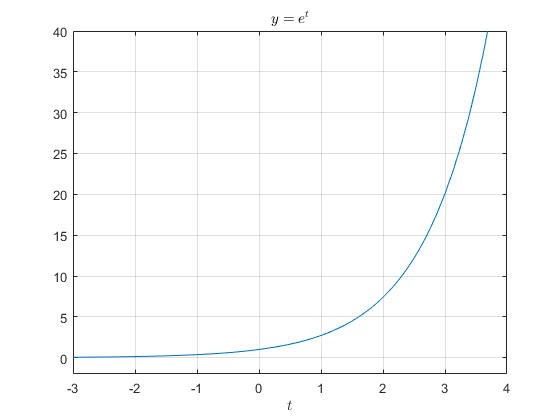

** Demostración **. Toma el mismo enfoque que usaste con $y=\cos(\theta)$ y calcula y grafica algunos valores del cociente de diferencias para $f(t) = e^t$ , 

$\text{Difference Quotient} = \frac{e^{t+h}-e^{t}}{h} = e^t\left(\frac{e^h-1}{h}\right)$. 

h = 0.2;          % User-defined step size, default h = 0.2
                      % Run this section
if ~exist("expTHandle","var") || ~isvalid(expTHandle)
    figure                                % Initialize a figure
    [expsHandle,expmptHandle,expTHandle] = GraphApproxDer(@(t)exp(t),"exp",h,[-3 4]);
    % GraphApproxDer is defined in Helper Functions
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    UpdateDerApprox(@(t)exp(t),"exp",h,[-3 4],expsHandle,expmptHandle,expTHandle)
end

  ** Intenta ** Establece algunos valores diferentes de `h` usando el control deslizante. Luego, comprueba tu hipótesis. Recuerda usar `t` como variable independiente. 

myGuess = @(t) exp(t);   % User-defined prediction of the derivative of exp(t)
                            % Run this section
CheckExpDer(myGuess);                 % checkExpDer is defined in Helper Functions
% checkExpDer compares myGuess to the derivative of exp(t)

### ** Aplicación: Crecimiento de la población **

Digamos que hay una población de conejos como esta: 

              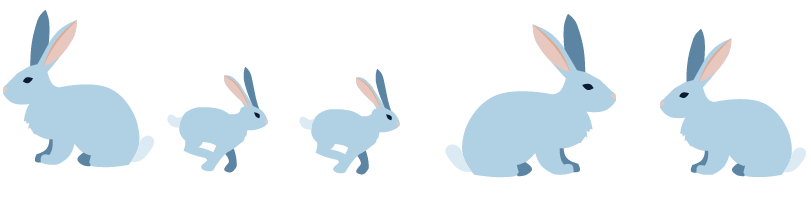    

Si la cantidad de conejos en el momento $t$ en años se modela mediante la función $B(t)$ , entonces la tasa de cambio de la cantidad de conejos a lo largo del tiempo está dada por la derivada $\frac{dB}{dt}$ con unidades de conejos por año. Digamos que en el momento $0$ la población de conejos es $100$ , ¿qué está sucediendo con la población de conejos a lo largo del tiempo si $\frac{dB}{dt} = B(t)$ ? 

 ** Reflexiona **

- ¿Qué tipo de función es su propia derivada? ¿Cómo puedes establecer el valor inicial en 100? 

- ¿Qué implica esto sobre la población de conejos a largo plazo? 

- ¿De qué manera es realista este modelo? ¿De qué manera es irreal? 

** Actividad **. La aproximación del cociente de diferencias a la derivada se puede utilizar para aproximar la solución de una ecuación diferencial con un valor inicial conocido. Digamos que hay 100 conejitos para empezar, así que $B(0)=100$. Cada año, suponga que todos los conejitos se reproducen una vez. Suponiendo que la población de conejos es mitad machos y mitad hembras y que el tamaño medio de la camada es $k$ , eso significa que el número de conejitos nuevos viene dado por $\frac{dB}{dt} = k\left(\frac{B(t)}{2}\right)$ , así que 

$\frac{B(t+h)-B(t)}{h} \approx k\left(\frac{B(t)}{2}\right)$. 

Por lo tanto, 

$B(t+h) = B(t) + hk\left(\frac{B(t)}{2}\right)$. 

  ** Pruebe **. El siguiente código implementa el modelo $B(t+h) = B(t)+k\left(\frac{B(t)}{2}\right)$ con $h=1$ año para `tEnd` años, utilizando la nueva población de conejos cada vez.Por lo tanto, 


$$B(1) = B(0+1) = B(0)+k\left(\frac{B(0)}{2}\right) = 100 + 50k$$
                                                        


$$B(2) = B(1+1) = B(1)+k\left(\frac{B(1)}{2}\right) = 100+50k + k\left(50+25k\right) = 100+100k+25k^2$$



$$\vdots$$
                                                                                                                  


$$B(\text{tEnd}) = B(\text{tEnd}-1)+k\left(\frac{B(\text{tEnd}-1)}{2}\right)$$
                                                                               

El código se ve así: 

Ejecute este código con diferentes opciones para el tamaño de la camada `k` y el número total de años, `tEnd,` y compare el número de conejos con la función de referencia $y(t) = 100e^t$ , que comienza en el mismo valor y crece exponencialmente.  ¿Cómo cambian tus resultados con diferentes valores para `k` ? Para `tEnd` ? 

k = 5;        %Tamaño de camada definido por el usuario, predeterminado k = 5
tEnd = 5;     %Año definido por el usuario tEnd, predeterminado tEnd = 5
                      %Ejecutar esta sección
tdata = 0:tEnd;             %Configurar un vector de tiempo
Bdata = size(tdata);        %Inicializar un vector para usar para la población de conejos
Bdata(1) = 100;             %Establecer B(0)=100
for j = 1:tEnd
    Bdata(j+1) = Bdata(j) + k*(Bdata(j)/2);    %Actualizar la población en cada paso de tiempo
end
figure                           %Inicializar una figura
plot(tdata,Bdata,"*-")           %Grafica la población de conejos calculada en función del tiempo
hold on
plot(tdata,100*exp(tdata),"*-")  % Add the plot of 100*e^t versus time
hold off
%Agrega un título, etiquetas y una leyenda al gráfico
title("Modelando la Población de Conejos")
xlabel("t (años)")
ylabel("# de Conejos")
legend("Modelo de Conejos con k = " + k, "y = 100e^t","Location","northwest")

**Reflexiona.**

- ¿Por qué las dos funciones son diferentes?

- ¿Cuál función está creciendo más rápido? ¿Por qué?

- ¿Puedes encontrar un parámetro k donde el Modelo de Conejos esté creciendo más lento que $100e^t$? ¿Puedes encontrar un parámetro k donde el Modelo de Conejos esté creciendo más rápido que $100e^t$?

#### Refinando el Modelo de Población

Como puedes ver, el primer Modelo de Población de Conejos es muy burdo, resultando en gráficos definidos por tramos que no se ven como curvas suaves porque solo estás verificando la población de conejos una vez al año. De hecho, los conejos maduran muy rápidamente y pueden tener varias camadas de crías cada año, así que permitamos un poco más de flexibilidad con el paso del tiempo con el mismo tEnd que arriba:

if ~exist("k","var")            % Configurar los parámetros predeterminados
    k = 5;                      % en caso de que la sección anterior no se haya ejecutado, k predeterminado = 5
end
if ~exist("tend","var")         % Configurar los parámetros predeterminados
    tEnd = 5;                   % en caso de que la sección anterior no se haya ejecutado, tEnd predeterminado = 5
end
dt = 0.25;  % Paso de tiempo definido por el usuario entre camadas (en años), dt predeterminado = 0.25
 
tData = 0:dt:tEnd;              % Configurar un vector de tiempo con tamaño de paso dt
BunnyData = size(tData);        % Inicializar un vector para la población de conejos
BunnyData(1) = 100;             % Establecer B(0)=100
for j = 1:length(tData)-1
    BunnyData(j+1) = BunnyData(j)+dt*(k/2)*BunnyData(j);   % Actualizar la población en cada paso de tiempo
end
figure                          % Inicializar una figura
plot(tData,BunnyData)           % Graficar la población de conejos calculada versus tiempo
hold on
syms t
fplot(100*exp(t),[0 tEnd])      % Añadir una gráfica de 100*e^t versus tiempo
hold off
title("Modelando la Población de Conejos")
xlabel("t (años)")
ylabel("# de Conejos")
if exist("Bdata","var") && exist("tdata","var") % Verificar si el modelo básico de conejos ya se ha ejecutado
    hold on
    scatter(tdata,Bdata,"filled")               % Añadir un diagrama de dispersión de la población de conejos con dt=1
    legend("Modelo Numérico con k = " + k + " y tamaño de paso " + dt,"y = 100e^t","Modelo Numérico " + ...
        "con k = " + k + " y tamaño de paso 1","Location","northwest")
    hold off
else                    % Recordar al usuario ejecutar la sección anterior y etiquetar solo las gráficas actuales
    disp("Ejecuta el Modelo de Conejos antes de esta sección para comparar los dos.")
    legend("Modelo Numérico con k = " + k + " y tamaño de paso " + dt,"y = 100e^t","Location","northwest")
end

 ** Reflexionar **

- ¿Cuál es el impacto en el modelo a medida que el tamaño del paso entre generaciones se acerca a 0? ¿Es realista permitir que el tamaño del paso se acerque a 0 aquí? ¿Por qué o por qué no? 

- ¿Qué tipo de función resuelve la ecuación diferencial $\frac{dy}{dx} = ky$ para $k$ una constante? ¿Importa lo que es $k$? 

- ¿Qué tipo de función resuelve la ecuación diferencial $\frac{dy}{dx} = kx$ para $k$ una constante? ¿Importa lo que es $k$? 

- ¿Cuál es la derivada $\frac{d}{dt}\left[e^{at}\right]$ para la constante $a$ ? 

##  Logaritmos 

Un logaritmo es la operación inversa a la exponenciación. Como se señaló anteriormente, el cálculo identifica un papel especial para un exponente con base $e$ , por lo que existe un papel correspondiente para el logaritmo natural $\ln(t) = \log_e(t)$. Hay una complicación adicional con los logaritmos porque el dominio de un logaritmo es $(0,\infty)$. 

** Actividad **. Prediga el tipo de función que será la derivada de un logaritmo natural y luego ejecute el código para generar un gráfico de la derivada aproximada de $\ln(t)$. 

h = 0.1;            %Tamaño de paso definido por el usuario h, predeterminado 0,1
    %Ejecutar esta sección
if ~exist("logTHandle","var") || ~isvalid(logTHandle)
    figure                                  %Inicializar una figura
    [logsHandle,logmptHandle,logTHandle] = GraphApproxDer(@(t)log(t),"ln",h,[0 8]);
    %GraphAppDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
else
    UpdateDerApprox(@(t)log(t),"ln",h,[0 8],logsHandle,logmptHandle,logTHandle)
end

  ** Intente ** Establezca el tamaño del paso en varios valores y prediga la función que es la derivada de $\ln(t)$. 

** Ejercicio 5 **. Considere el gráfico del valor aproximado de la derivada $\frac{d}{dt}\left[\ln(t)\right]$. 

- ¿Podría la derivada ser una función polinómica? ¿Por qué o por qué no? 

poly = "idk";   %Respuesta definida por el usuario al Ejercicio 5.1
%Interactuar con el usuario en función de sus elecciones
if poly == "yes"
    disp("Todos los polinomios p(t) divergen hacia el infinito positivo o negativo a medida que t tiende a infinito.")
    disp("Eso no es cierto para esta derivada. No es un polinomio.")
elseif poly == "no"
    disp("Eso es correcto.")
    disp("Esto no puede ser un polinomio porque no tiene el comportamiento límite correcto.")
end 

2. ¿La derivada tiene asíntotas? ¿Por qué o por qué no? Si hay asíntotas, ¿cuáles son? 

asymptotes = "yHoriz"; %Respuesta definida por el usuario al Ejercicio 5.2
%Interactuar con el usuario en función de sus elecciones
if asymptotes == "yHoriz"
    disp("Sí, hay una asíntota horizontal.")
    disp("Ajusta la asíntota horizontal al valor correcto:")
    yasymp = 3;     %A medida que el usuario actualiza este valor, la sección se ejecutará nuevamente
    xasymp = 3;     %A medida que el usuario actualiza este valor, la sección se ejecutará nuevamente
    GraphApproxDer(@(t)log(t),"ln",h,[0 8]);     %GraphAppDer está definido en Funciones auxiliares
    % GraphApproxDer plots a function and calculates and plots its numerical
    % derivative with step size h
    hold on
    plot([0 8],[yasymp yasymp],"--",SeriesIndex=1);  %Dibuje la asíntota horizontal propuesta para referencia
    %Configurar el formato de la cadena del título
    formatTitle = "Aproximando la derivada de $y = \\%s(t)$ con tama\\~no de paso $h=%.2f$";
    if ~exist("h","var")
        h = 0.1;                       % Si es necesario, establezca el valor predeterminado para el tamaño del paso
    end
    str = compose(formatTitle,"ln",h); % Incluya el nombre de la función y el tamaño del paso
    title(str,"As\`intota $y=$" + yasymp,"Interpreter","latex")
    hold off
    if yasymp == 0
        disp("Eso es correcto, la asíntota horizontal está en y=0.")
    end
elseif asymptotes == "yVert"
    disp("No, no hay una asíntota vertical. Por favor, intenta de nuevo.")
elseif asymptotes == "no"
    disp("Sí, hay una asíntota. ¿Qué tipo es?")
end 

3. ¿La derivada es periódica? ¿Por qué o por qué no? Si es periódica, ¿cuál es el período y cuál es la amplitud? 

periodic = -1;   %Respuesta definida por el usuario al Ejercicio 5.3
%Interactuar con el usuario en función de sus elecciones
period = "2*pi";          amplitude = "1";
if periodic == 1
    disp("No, esta derivada no es periódica. Por favor, intenta de nuevo.")
elseif periodic == 0
    disp("Eso es correcto. Esta derivada no es periódica.")
end 

4. Juntando todos los hechos establecidos en el Ejercicio 5, partes 1 a 3, identifique la familia funcional de la derivada del logaritmo natural. 

%Respuesta definida por el usuario a "¿Qué tipo de función es la derivada de un logaritmo natural? 
lnDerGuessType = "unknown";
CheckLnDerGuessType(lnDerGuessType);  %checkLnDerGuessType está definido en Funciones auxiliares
% checkLnDerGuessType plots a best-fit curve of form lnDerGuessType and provides
% written feedback to the function type selected and information about the goodness of fit

 ** Reflexiona **

- Usa la aproximación numérica o las reglas del logaritmo para determinar la derivada $\frac{dy}{dx}$ de $y = \ln(cx)$ donde $c$ es una constante. ¿Coincide esto con lo que encontraste para las otras funciones? ¿Por qué o por qué no? 

- ¿Qué encuentras con diferentes opciones para el Ejercicio 5, parte 4? 

###  Aplicación de práctica 

Si prefieres practicar en la aplicación Calculus Flashcards, puedes comenzar haciendo clic en la imagen a continuación. Debes configurarla para "Derivadas de funciones" en la sección Derivadas. La aplicación se abrirá en una nueva ventana. 

[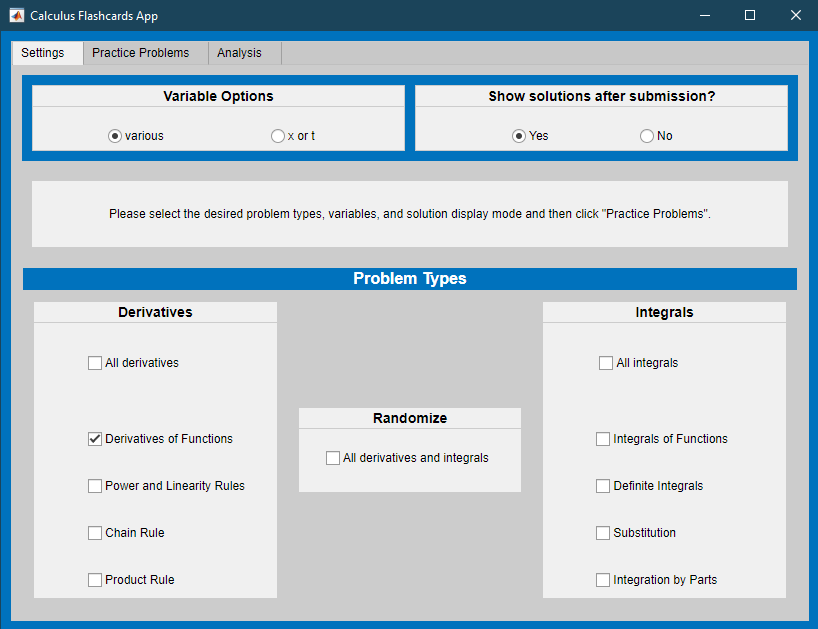](matlab: CalculusFlashcards)

run("TarjetasDeCalculo")
 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si deseas ver los detalles del código, selecciona la pestaña ** View ** y cambia a ** Output inline**. Alternativamente, selecciona ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

function CheckSinDer(fh)
%CheckSinDer toma un manejador de función y verifica si es equivalente
% a cos(t)
%
%fh es un controlador de función
syms t                             %Crear una variable simbólica t
if cos(t) == fh(t)                 %Comparar la función simbólica cos(t) y fh(t)
    disp("Correcto.")               % Si son idénticos, mostrar "Correcto"
elseif cos(t) == simplify(fh(t))   % Si son equivalentes, mostrar comentarios adicionales
    disp("Correcto. Sin embargo, es más común escribir cos(t).")
else                               % Si la respuesta es incorrecta, incluir una sugerencia
    disp("Incorrecto. ¿Qué otras funciones sinusoidales conoces?")
end
end

function [sHandle,mptHandle,gTHandle,fHandle]=GraphApproxDer(fh,fs,dt,bds)
%GraphAppDer traza una función y calcula y traza su derivada numérica
% con un tamaño de paso dt
%
%fh es un controlador de función para la función que se va a graficar
% fs es el mismo nombre de función que una cadena
% dt es el tamaño del paso
% bds es un vector 1x2 [límite inferior límite superior]
syms t                 %Crear una variable simbólica t
figure                 %Crear una nueva figura
fHandle = fplot(fh(t),bds);      %Dibuje la función fh(t) simbólicamente sobre el dominio bds
if bds(1) == -pi       %Etiquete el gráfico para funciones trigonométricas
    formatTitle = "Aproximando la derivada de $y = \\%s(\\theta)$ con tama\\~no de paso $h=$%.2f";
    xticks(-pi:pi/2:3*pi)
    xticklabels(["-\pi","-\pi/2","0","\pi/2","\pi","3\pi/2","2\pi","5\pi/2","3\pi"])
    formatLegend1 = "$\\%s(\\theta)$";
    formatLegend2 = "Cociente Diferencial: $\\left(\\theta, \\frac{\\%s(\\theta+h)-\\%s(\\theta)}{h}\\right)$";
    formatPts = "Puntos Seleccionados: $\\left(\\theta, \\%s(\\theta)\\right)$";
else                   % Etiquete el gráfico para funciones exponenciales/logarítmicas
    formatTitle = "Aproximando la derivada de $y = \\%s(t)$ con tama\\~no de paso $h=$%.2f";
    xticks(linspace(bds(1),bds(2),bds(2)-bds(1)+1));
    xticklabels(bds(1):bds(2));
    formatLegend1 = "$\\%s(t)$";
    formatLegend2 = "Cociente Diferencial: $\\left(t,\\frac{\\%s(t+h)-\\%s(t)}{h}\\right)$";
    formatPts = "Puntos Seleccionados: $\\left(t,\\%s(t)\\right)$";
end
%Anote el gráfico con un título, etiquetas de ejes y leyenda
graphTitle = compose(formatTitle,fs,dt);
line1 = compose(formatLegend1,fs);
line2 = compose(formatLegend2,fs,fs);
pts = compose(formatPts, fs);
gTHandle = title(graphTitle,"Interpreter","latex");
tVals = bds(1):dt:bds(2);
yVals = fh(tVals);
hold on
sHandle = scatter(tVals,yVals,100,".",SeriesIndex=2);  %Grafica los puntos utilizados para la aproximación numérica de la derivada
hold off
derVals = (yVals(2:end)-yVals(1:end-1))/dt; %Calcula la derivada numérica utilizando el cociente de diferencias
mdPts = (tVals(2:end)+tVals(1:end-1))/2;    %Determinar los puntos medios del intervalo para graficar
hold on
try
    mptHandle = scatter(mdPts,derVals,30,"square",SeriesIndex="none"); %Dibuje (punto medio, pendiente de la línea secante para ese intervalo)
catch
    mptHandle = scatter(mdPts,derVals,30,"k","square");
end
legend(line1,pts,line2,...
    "Interpreter","latex","Location","southoutside","AutoUpdate","off")
hold off
end

function UpdateDerApprox(fh,fs,dt,bds,sHandle,mptHandle,gTHandle)
if bds(1) == -pi       %Etiquete el gráfico para funciones trigonométricas
    formatTitle = "Aproximando la derivada de $y = \\%s(\\theta)$ con tama\\~no de paso $h=$%.2f";
else                   % Etiquete el gráfico para funciones exponenciales/logarítmicas
    formatTitle = "Aproximando la derivada de $y = \\%s(t)$ con tama\\~no de paso $h=$%.2f";
end
%Anote el gráfico con un título, etiquetas de ejes y leyenda
gTHandle.String = compose(formatTitle,fs,dt);
tVals = bds(1):dt:bds(2);
yVals = fh(tVals);
sHandle.XData = tVals;                      %Actualizar los puntos
sHandle.YData = yVals;
derVals = (yVals(2:end)-yVals(1:end-1))/dt; %Calcula la derivada numérica utilizando el cociente de diferencias
mdPts = (tVals(2:end)+tVals(1:end-1))/2;    %Determinar los puntos medios del intervalo para graficar
mptHandle.XData = mdPts;                    %Actualizar la línea del punto medio
mptHandle.YData = derVals;
end

function GraphDerGuess(fh,mult)
%GraphDerGuess traza la función dada por fh con un cambio de fase de mult*pi
% y agrega una anotación que indica que \phi = mult*pi en el gráfico
% en el cuadrante inferior izquierdo del gráfico
%
%fh es un controlador de función y mult es un número
syms t                       %Crear una variable simbólica t
%Grafica y=(fh(t+mult*pi)) simbólicamente en el dominio [-pi,3*pi] con una línea azul
% de ancho 2
fplot(fh(t+mult*pi),[-pi 3*pi],"-","LineWidth",2,SeriesIndex=1)
dim = [.22 .25 .2 .2];       %Define la ubicación relativa (.22,.25) para la esquina de un cuadrado de lado .2
[num,den] = rat(abs(mult));  %Encuentra el numerador y el denominador de la forma racional de |mult|
if mult < 0                  %Corrija el signo del numerador para que coincida con el signo de mult
    num = -num;
end
%Imprimir phi de manera elegante
if den ~= 1 && abs(num) ~= 1      %Si mult no es un entero ni una fracción unitaria
    formatStr = "$\\phi = \\frac{%d\\pi}{%u}$";
    str = compose(formatStr, num, den);
elseif den ~= 1 && num == 1  %Si mult es una fracción unitaria
    formatStr = "$\\phi = \\frac{\\pi}{%u}$";
    str = compose(formatStr, den);
elseif den ~= 1 && num == -1  %Si mult es una unidad negativa fracción
    formatStr = "$\\phi = \\frac{-\\pi}{%u}$";
    str = compose(formatStr, den);
elseif num == 1 && den == 1  %Si mult es 1
    str = "$\\phi = \\pi$";
elseif num == -1 && den == 1 %Si mult es -1
    str = "$\\phi = -\\pi$";
elseif num == 0              %Si mult es 0
    str = "$\\phi = 0$";
else
    formatStr = "$\\phi = %d\\pi$";
    str = compose(formatStr,num);
end
%Anota el gráfico con el valor de phi en un cuadro con borde blanco en dim
annotation("textbox",dim,"String",str,"FitBoxToText","on",...
    "Interpreter","latex","EdgeColor",[1 1 1])
%Agregar una leyenda
legend(["$\cos(\theta)$" "Puntos Seleccionados" "Derivada Aproximada" "$\cos(\theta+\phi)$"],"Interpreter","latex")
end

function CheckCosDer(fh)
%CheckCosDer compara la función -sin(t) con fh(t) e imprime un mensaje
% de éxito o fracaso utilizando disp()
%
%fh es un controlador de función
syms t                             %Crear una variable simbólica
if -sin(t) == fh(t)                %Verifique si -sin(t) == fh(t) como funciones simbólicas
    disp("Correcto.")
elseif -sin(t) == simplify(fh(t))  % Si -sin(t) es equivalente a fh(t) como funciones simbólicas
    disp("Correcto. Sin embargo, es más común escribir -sin(t).")
else                               % Mostrar comentarios
    disp("Incorrecto. Intenta encontrar una mejor coincidencia.")
end
end

function [n,gyOpts] = SetOptions(gUnits,yUnits)
%gyOpts configura las opciones de unidad y selecciona la potencia n
%
%gUnits son las unidades de la variable dependiente
% yUnits son las unidades de la variable independiente
n = randi([2 5]);              %Seleccionar un entero aleatorio del conjunto {2,3,4,5}
switch n                       %Establecer la cadena n-ésima correcta para el texto de la pregunta
    case 2
        nth = "segunda";
    case 3
        nth = "tercera";
    case 4
        nth = "cuarta";
    case 5
        nth = "quinta";
end
formatgy = "%s/%s";            % Establecer la cadena de formato para las primeras derivadas
formatgy2 = "%s/%s^2";         % Establecer la cadena de formato para las segundas derivadas
formatgy3 = "%s/%s^3";         % Establecer la cadena de formato para las terceras derivadas
formatgy4 = "%s/%s^4";         % Establecer la cadena de formato para las cuartas derivadas
formatgy5 = "%s/%s^5";         % Establecer la cadena de formato para las quintas derivadas
% Crear cadenas para cada opción, incluidas las unidades g y y definidas por el usuario
gyOpts = compose([formatgy,formatgy2,formatgy3,formatgy4,formatgy5],gUnits,yUnits);
% Hacer la pregunta
disp("Si n = "+n+", entonces la "+nth+" derivada de g con respecto a y tiene unidades de:")
% Mostrar las posibles soluciones
disp("Opción 1: " + gyOpts(1))
disp("Opción 2: " + gyOpts(2))
disp("Opción 3: " + gyOpts(3))
disp("Opción 4: " + gyOpts(4))
disp("Opción 5: " + gyOpts(5))
end

function CheckGYUnits(myAnswer,n)
%CheckGYUnits compara myAnswer con el valor n
%
%myAnswer es un entero en el rango 1-5
% n es un entero en el rango 2-5
if myAnswer == n           %Verificar si la respuesta es correcta
    disp("¡Correcto!")
else                       % Dar comentarios y sugerencias si la respuesta es incorrecta
    disp("Recuerda que cada derivada implica dividir por las unidades de la variable independiente.")
    disp("Por favor, intenta de nuevo.")
end
end

function CheckEqns(a,b,c,d)
%CheckEqns verifica la veracidad de a, b, c y d e imprime comentarios
%
%a, b, c y d son valores booleanos
if ~a && b && c && d     %Dar comentarios si la respuesta es correcta
    disp("¡Correcto!")
    disp("Cualquier combinación lineal de senos y cosenos será una solución a esta ecuación diferencial.")
else                     % Da retroalimentación y una pista si una o más de las respuestas son incorrectas
    disp("Por favor, revisa tus derivadas.")
    disp("Una de estas funciones no funciona y tres de ellas sí.")
    disp("¿Por qué?")
end
end

function CheckExpDer(myGuess)
%CheckExpDer compara myGuess con exp(t)
%
%myGuess es un controlador de función
syms t                    %Crear una variable simbólica
if myGuess == exp(t)      %Si myGuess es correcto, mostrar comentarios
    disp("¡Correcto!")
    disp("Todas las funciones de la forma a^x para constante a y variable x tienen derivadas")
    disp("que son múltiplos de la original, pero solo para e^x ese múltiplo es 1.")
else                      % Si myGuess es incorrecto, muestra comentarios, un gráfico y una pista
    disp("Incorrecto. ¿A qué función se parece esto?")
    disp("Recuerda que la sintaxis de MATLAB para una exponencial e^x es exp(x).")
    fplot(myGuess,[-3 4])
    hold on
    fplot(exp(t),[-3 4])
    hold off
    legend("Mi Suposición","Derivada de $e^t$","Interpreter","latex","Location","northwest")
    ylim([-3 40])
end
end

function CheckLnDerGuessType(myAnswer)
%CheckLnDerGuessType traza una curva de mejor ajuste de la forma myAnswer y proporciona
% comentarios escritos sobre el tipo de función seleccionado y
% información sobre la bondad del ajuste
%
%myAnswer es una cadena del conjunto
% ["unknown" "exponential" "polilynomial" "rational"]
tData = 0.01:.005:10;                    %Establezca un vector de fila de 0,01 a 10 con un tamaño de paso de 0,005
tData = tData';                          %Convertirla en un vector columna
tMid = (tData(2:end)+tData(1:end-1))/2;  %Encuentre los puntos medios de cada intervalo para graficar
DQCalc = (log(tData(2:end))-log(tData(1:end-1)))/.005; %Calcular las pendientes de las secantes
switch myAnswer                          %Dar comentarios en función de la user-solution
    case "unknown"                       %Valor predeterminado, fomentar el esfuerzo
        disp("Puedes hacerlo mejor que eso. La respuesta es un tipo de función familiar.")
        return
    case "exponencial"                   % Comentarios, incluido el gráfico de un ajuste exponencial óptimo
        disp("No, la derivada de un logaritmo no es una función exponencial.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"exp1");
    case "polinómica"                    % Comentarios, incluido el gráfico de un polinomio de grado 5 de mejor ajuste
        disp("No, la derivada de un logaritmo no es un polinomio.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"poly5");
    case "racional"                      % Comentarios, incluyendo el gráfico de un ajuste racional óptimo
        disp("Sí, la derivada de un logaritmo es una función racional.")
        [fnFit,fnGoF] = fit(tMid,DQCalc,"rat33","StartPoint",[0 1 0 0 0 0 0]);
end
%Grafique el mejor ajuste del tipo funcional elegido
plot(fnFit,tMid,DQCalc)
ylim([-5 30]);                           %Establecer los límites y para una visualización óptima
disp(fnFit)                              %Imprimir información sobre el mejor ajuste
%Proporciona orientación sobre cómo interpretar la bondad del ajuste
disp(" ")
disp("El mejor ajuste de este tipo tiene un SSE de " + fnGoF.sse + " y un r^2 de " + fnGoF.rsquare + ".")
disp(" ")
disp("Los buenos ajustes tienen un SSE cercano a 0 y un r^2 cercano a 1. ¿Qué opinas?")
% Si myAnswer es correcta, reconoce y proporciona la solución analítica
if myAnswer == "racional"
    disp(" ")
    disp("De hecho, la derivada de ln(t) es 1/t.")
end
end

function UnitCircleAnimation()
%UnitCircleAnimation crea un gráfico grande del círculo unitario con un triángulo rectángulo inscrito animado
% y dos gráficos pequeños que rastrean el coseno y el seno
% del ángulo en el centro del círculo. Realiza un bucle
% dos veces alrededor del círculo completo en el transcurso de 2,5 segundos
tAll = linspace(0,2*pi,1000);     %Definir un vector t de 1e3 puntos de 0 a 2*pi
tPts = linspace(-pi,3*pi,10000);  %Define una malla más fina de 1e4 puntos desde -pi hasta 3*pi
xVals = cos(tAll);                %Calcular los valores x cos(t) para tAll
yVals = sin(tAll);                %Calcular los valores y sin(t) para tAll
subplot(2,3,[1 2 4 5])            %Configura un conjunto de gráficos de 2x3 y selecciona el 2x2 en la parte superior izquierda
plot(xVals,yVals)                 %Dibuje el círculo (cos(t), sen(t)) para t de 0 a 2*pi
%Agregar un título, configurar los límites y las etiquetas
title(["$x^2+y^2=1$ y el tri\'{a}ngulo rect\'{a}ngulo" "$(0,0)$, $(x,0)$, $(x,y)$"],"Interpreter","latex")
xlim([-1.1 1.1])
ylim([-1.1 1.1])
axis square
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
hold on
try
    scatter(0,0,"o","filled",SeriesIndex="none")        %Marcar el centro del círculo
catch
    scatter(0,0,"ko","filled")
end
startPt = -pi-6*pi/500;           %Defina un punto inicial en el tiempo para iniciar la animación
cosStartPt = cos(startPt);        %Calcular el valor inicial del coseno (x)
sinStartPt = sin(startPt);        %Calcular el valor inicial del seno (y)
%Define objetos de trazado para los lados y vértices móviles del triángulo
% El uso de esta estructura acelera drásticamente la representación de la figura
p1 = plot([0 cosStartPt],[0 0],"-","LineWidth",2,"SeriesIndex",1);
p2 = plot([0 cosStartPt],[0 sinStartPt],"-","LineWidth",2,"SeriesIndex",1);
p3 = plot([cosStartPt cosStartPt],[0 sinStartPt],"-","LineWidth",2,"SeriesIndex",1);
s1 = scatter(cosStartPt,0,"o","filled","SeriesIndex",3,"MarkerEdgeColor","m");
s2 = scatter(cosStartPt,sinStartPt,"o","filled","SeriesIndex",2);
hold off
subplot(2,3,3)                    %Identificar el subgráfico superior derecho
plot(tPts,sin(tPts));             %Graficar y = sen(t) para t en [0, 2*pi]
hold on
%Agregar un título, configurar los límites y las etiquetas
title("$y = \sin(\theta)$","Interpreter","latex")
xlabel("$\theta$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
xlim([-pi,3*pi])
axis square
%Definir un objeto de diagrama de dispersión para rastrear el valor de sin(t)
s3 = scatter(startPt,sinStartPt,"o","filled","SeriesIndex",2);
hold off
subplot(2,3,6)                    %Identificar el subgráfico inferior derecho
plot(tPts,cos(tPts));             %Graficar y = cos(t) para t en [0, 2*pi]
hold on
%Agregar un título, configurar los límites y las etiquetas
title("$x = \cos(\theta)$","Interpreter","latex")
xlabel("$\theta$","Interpreter","latex")
ylabel("$x$","Interpreter","latex")
xlim([-pi,3*pi])
axis square
%Define un objeto de gráfico de dispersión para rastrear el valor de cos(t)
s4 = scatter(startPt,cosStartPt,"o","filled","MarkerEdgeColor","m","SeriesIndex",3);
hold off
for t0 = linspace(-pi,3*pi,501)   %para 501 puntos desde -pi hasta 3*pi
    p1.XData = [0 cos(t0)];       %Actualice los datos x para el lado horizontal del triángulo
    p2.XData = [0 cos(t0)];       %Actualice los datos x para la hipotenusa del triángulo
    p2.YData = [0 sin(t0)];       %Actualice los datos y para la hipotenusa del triángulo
    p3.XData = [cos(t0) cos(t0)]; %Actualice los datos x para el lado vertical del triángulo
    p3.YData = [0 sin(t0)];       %Actualice los datos y para el lado vertical del triángulo triángulo
    s1.XData = cos(t0);           %Actualiza los datos x para el punto que sigue el vértice del ángulo recto
    s2.XData = cos(t0);           %Actualiza los datos x para el punto que sigue el vértice agudo en movimiento
    s2.YData = sin(t0);           %Actualiza los datos y para el punto que sigue el vértice agudo en movimiento
    s3.XData = t0;                %Actualizar los datos x para el gráfico del seno
    s3.YData = sin(t0);           %Actualizar los datos y para el gráfico del seno
    s4.XData = t0;                %Actualizar los datos x para el gráfico de coseno
    s4.YData = cos(t0);           %Actualizar los datos y para el gráfico de coseno
    %pause(0) % Opcionalmente incluye el tiempo antes de comenzar el siguiente bucle iteración
    drawnow                       %Forzar la representación del gráfico antes de realizar un bucle
end
end 